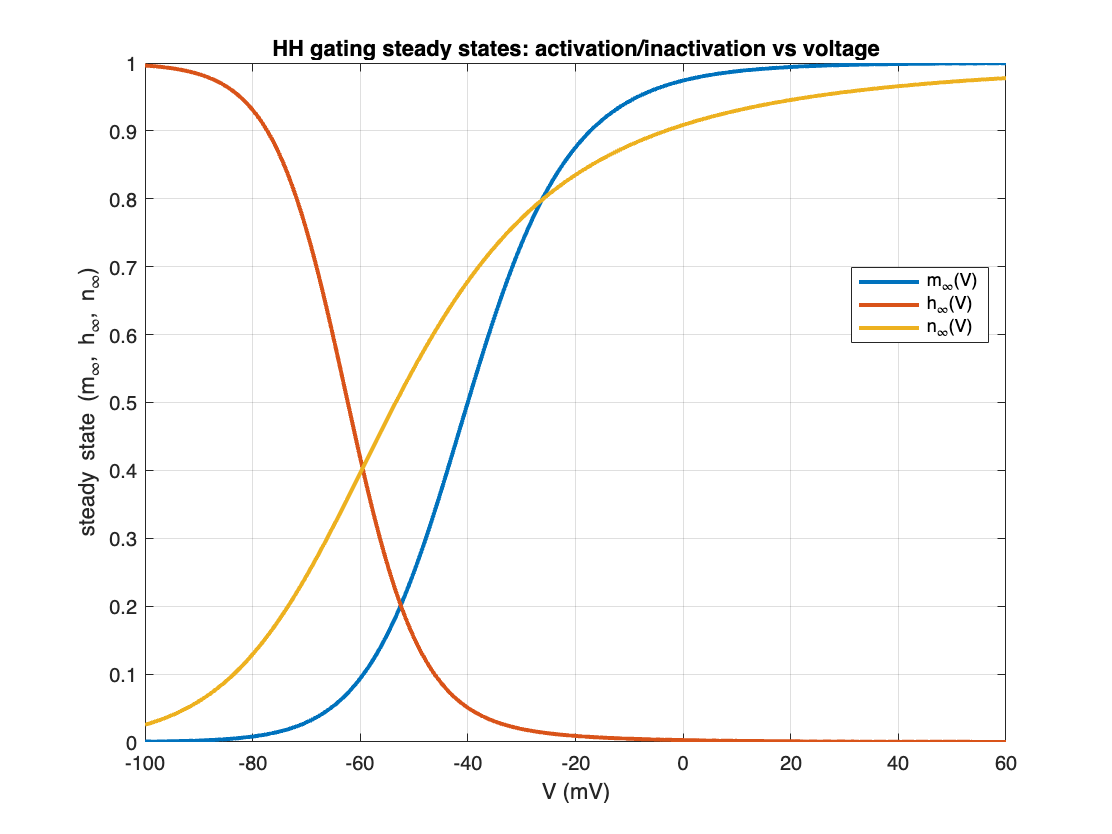


%% ex1_HH_to_FHN_slowfast_demo.m
% Recitation Demo (Complex Systems): Hodgkin--Huxley (HH) neuron model,
% slow--fast viewpoint, and a 2D reduction + FitzHugh--Nagumo (FHN) caricature.
%
% Goals:
%   (a) Visualize HH biophysics: gating variables, conductances, ionic currents.
%   (b) Illustrate slow--fast structure (m fast; h,n slow) and compare HH vs FHN.
%   (c) Show how a reduced phase portrait changes as a slow HH variable varies.
%
% Notes:
%   - This script is intentionally figure-heavy but "teaching-friendly".
%   - No toolboxes required beyond base MATLAB ODE solvers.
%   - Units: membrane potential V in mV, time in ms, currents in uA/cm^2.
%
% Reference parameter set: classic squid giant axon (Hodgkin & Huxley 1952).
%
% -------------------------------------------------------------------------

clear; close all; clc;

%% --------------------------- USER CONTROLS -----------------------------
% Stimulus current: step current I(t) = I0 for t >= t_on
I0   = 10;         % uA/cm^2 (try 6-12)
t_on = 5;          % ms
t_off = 45;        % ms (set <Tend for finite pulse; set >Tend for sustained)

Tend = 50;         % ms
Vrest = -65;       % mV (typical resting potential)

% Choose solver: HH can be stiff depending on current and tolerances.
useStiffSolver = true; % true -> ode15s, false -> ode45

% 2D reduction: choose a constant h ("slow variable") to see phase portrait shift
h_values_for_nullcline_scan = [0.05 0.1 0.2 0.4 0.6];   % demonstrate effect of slow Na-inactivation

% FitzHugh--Nagumo parameters (one convenient spiking set)
FHN.eps = 0.08;
FHN.a   = 0.7;
FHN.b   = 0.8;
FHN.I   = 0.5;     % increase slightly to drive oscillations, decrease for excitable only
FHN.Tend = 200;    % longer because FHN is dimensionless and slower

%% ---------------------- HH PARAMETERS (CLASSIC) ------------------------
HH.Cm  = 1.0;      % uF/cm^2
HH.gNa = 120;      % mS/cm^2
HH.gK  = 36;       % mS/cm^2
HH.gL  = 0.3;      % mS/cm^2
HH.ENa = 50;       % mV
HH.EK  = -77;      % mV
HH.EL  = -54.4;    % mV

% A "handle" for external current injection
Iapp = @(t) I_step(t, I0, t_on, t_off);

%% ----------------- FIGURE A: STEADY-STATE GATING CURVES ----------------
% Key slow--fast fact in HH: m is fast, h and n are slower.
Vgrid = linspace(-100, 60, 800);

[m_inf, tau_m] = gate_inf_tau(Vgrid, @alpha_m, @beta_m);
[h_inf, tau_h] = gate_inf_tau(Vgrid, @alpha_h, @beta_h);
[n_inf, tau_n] = gate_inf_tau(Vgrid, @alpha_n, @beta_n);

figure('Name','HH gating steady states');
plot(Vgrid, m_inf, 'LineWidth', 2); hold on;
plot(Vgrid, h_inf, 'LineWidth', 2);
plot(Vgrid, n_inf, 'LineWidth', 2);
grid on; xlabel('V (mV)'); ylabel('steady state (m_\infty, h_\infty, n_\infty)');
legend('m_\infty(V)','h_\infty(V)','n_\infty(V)','Location','best');
title('HH gating steady states: activation/inactivation vs voltage');

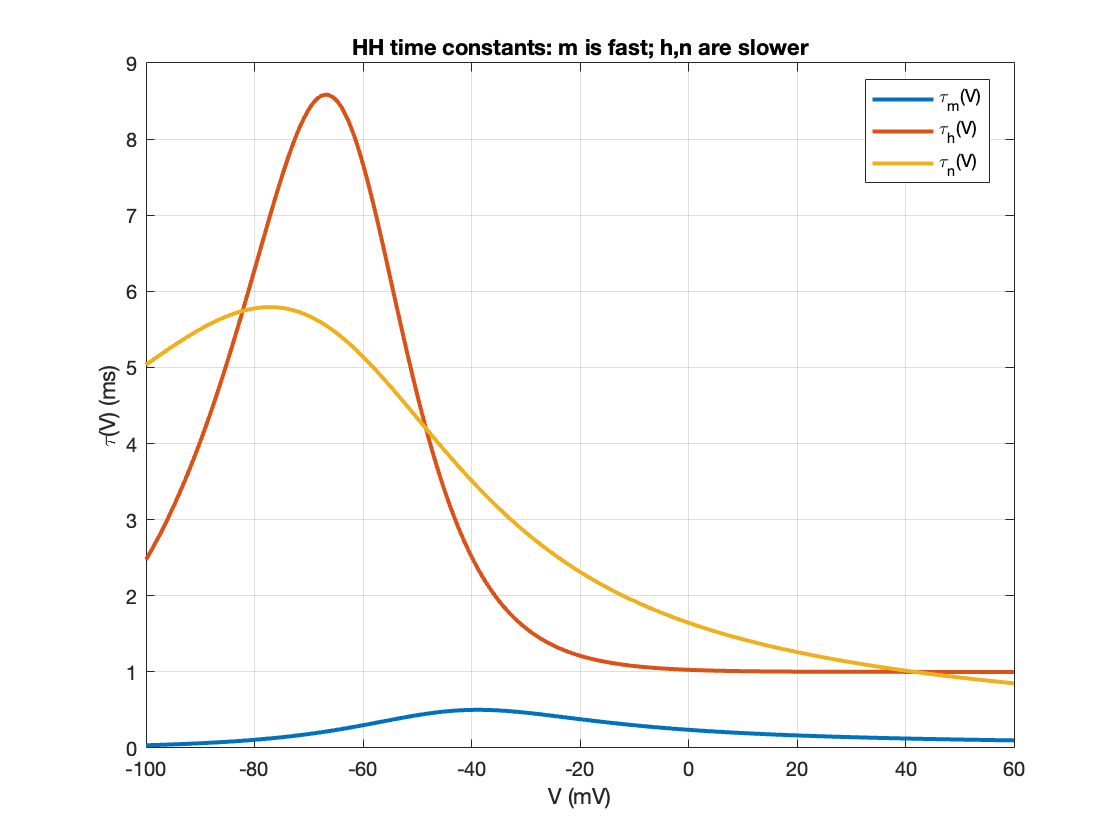

% [Insert slide image: three sigmoid-like curves for m_inf, h_inf, n_inf]

figure('Name','HH gating time constants');
plot(Vgrid, tau_m, 'LineWidth', 2); hold on;
plot(Vgrid, tau_h, 'LineWidth', 2);
plot(Vgrid, tau_n, 'LineWidth', 2);
grid on; xlabel('V (mV)'); ylabel('\tau(V) (ms)');
legend('\tau_m(V)','\tau_h(V)','\tau_n(V)','Location','best');
title('HH time constants: m is fast; h,n are slower');

% [Insert slide image: tau_m much smaller than tau_h,tau_n over most V]

%% ----------------- SIMULATE FULL 4D HH MODEL (V,m,h,n) -----------------
% Initial gating at rest: set to their steady states at Vrest
m0 = gate_inf_tau(Vrest, @alpha_m, @beta_m);
h0 = gate_inf_tau(Vrest, @alpha_h, @beta_h);
n0 = gate_inf_tau(Vrest, @alpha_n, @beta_n);

X0 = [Vrest; m0; h0; n0];

odefunHH = @(t,X) HH_rhs(t, X, HH, Iapp);

opts = odeset('RelTol',1e-7,'AbsTol',1e-9,'MaxStep',0.05);
tspan = [0 Tend];

if useStiffSolver
    solver = @ode15s;
else
    solver = @ode45;
end

fprintf('Simulating full HH model with %s...\n', func2str(solver));

Simulating full HH model with ode15s...


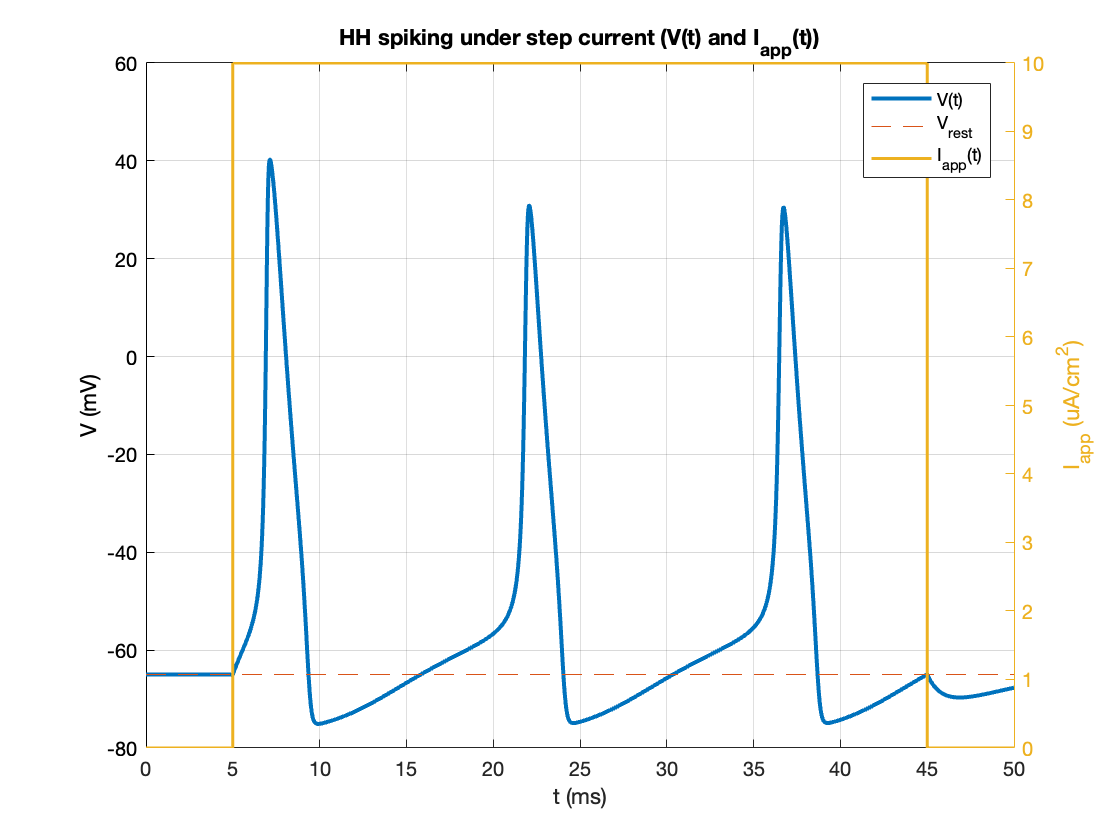

[tHH, XHH] = solver(odefunHH, tspan, X0, opts);

V = XHH(:,1); m = XHH(:,2); h = XHH(:,3); n = XHH(:,4);

% Compute biophysical outputs: currents and conductances
gNa_eff = HH.gNa .* (m.^3) .* h;  % effective sodium conductance
gK_eff  = HH.gK  .* (n.^4);       % effective potassium conductance

INa = gNa_eff .* (V - HH.ENa);
IK  = gK_eff  .* (V - HH.EK);
IL  = HH.gL   .* (V - HH.EL);
Iinj = arrayfun(Iapp, tHH);

%% Figure B1: membrane potential + stimulus
figure('Name','HH membrane potential');
plot(tHH, V, 'LineWidth', 2); hold on;
plot(tHH, Vrest*ones(size(tHH)), '--');
yyaxis right;
plot(tHH, Iinj, 'LineWidth', 1.5);
ylabel('I_{app} (uA/cm^2)');
yyaxis left;
grid on; xlabel('t (ms)'); ylabel('V (mV)');
title('HH spiking under step current (V(t) and I_{app}(t))');
legend('V(t)','V_{rest}','I_{app}(t)','Location','best');

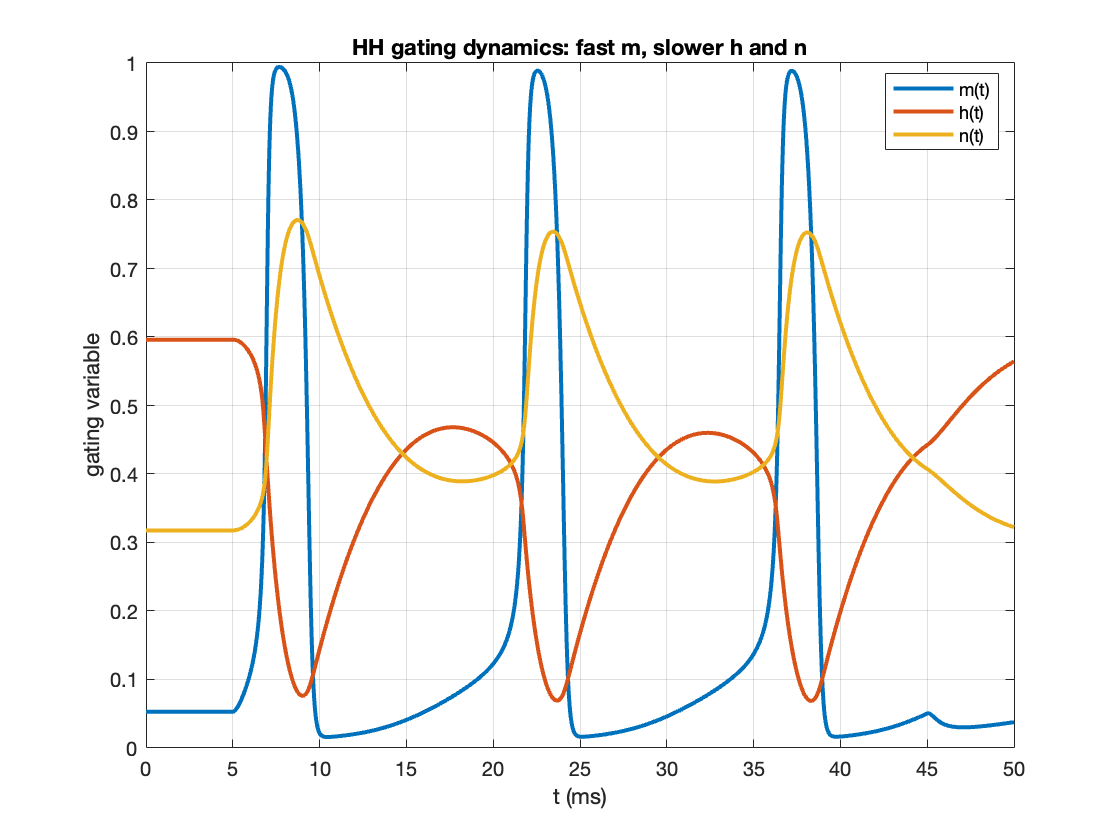

% [Insert slide image: V(t) with spikes + step current]

%% Figure B2: gating variables vs time
figure('Name','HH gating variables');
plot(tHH, m, 'LineWidth', 2); hold on;
plot(tHH, h, 'LineWidth', 2);
plot(tHH, n, 'LineWidth', 2);
grid on; xlabel('t (ms)'); ylabel('gating variable');
legend('m(t)','h(t)','n(t)','Location','best');
title('HH gating dynamics: fast m, slower h and n');

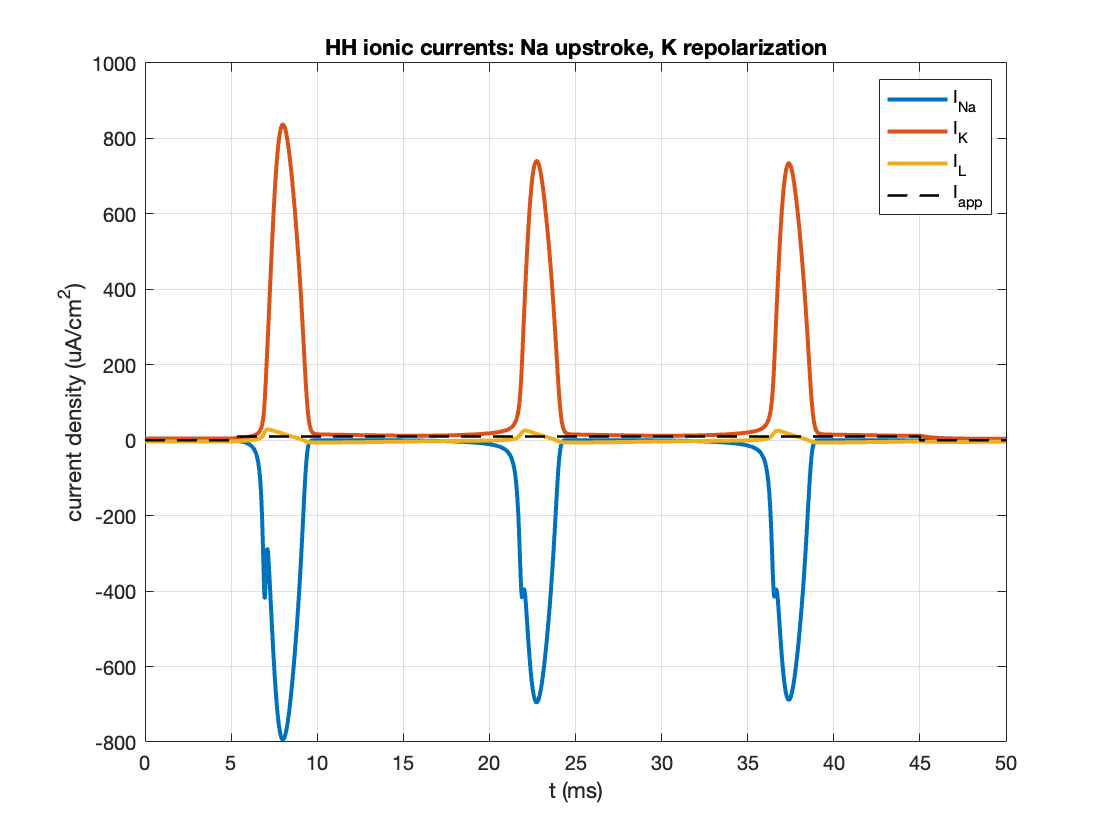

% [Insert slide image: m responds quickly; h,n evolve slower]

%% Figure B3: ionic currents (interpretation of spike shape)
figure('Name','HH ionic currents');
plot(tHH, INa, 'LineWidth', 2); hold on;
plot(tHH, IK,  'LineWidth', 2);
plot(tHH, IL,  'LineWidth', 2);
plot(tHH, Iinj,'k--','LineWidth',1.2);
grid on; xlabel('t (ms)'); ylabel('current density (uA/cm^2)');
legend('I_{Na}','I_{K}','I_{L}','I_{app}','Location','best');
title('HH ionic currents: Na upstroke, K repolarization');

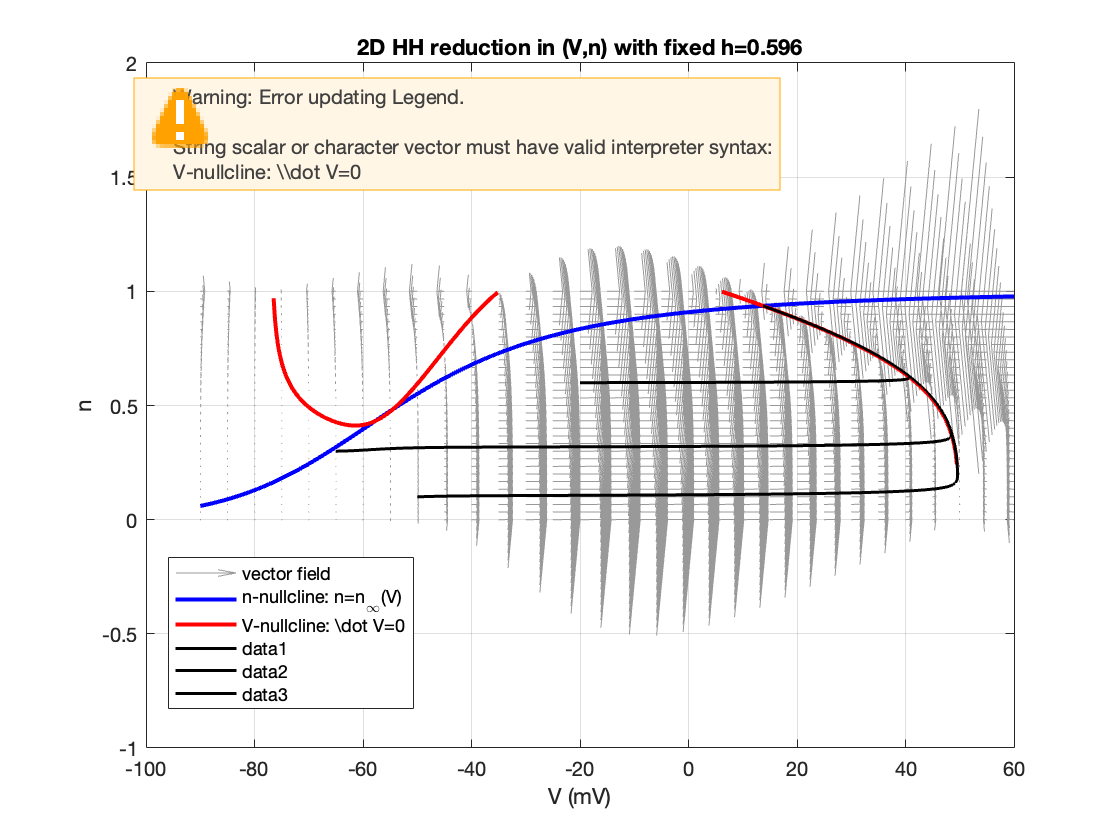

% [Insert slide image: Na current brief negative; K positive longer]

%% ----------------- SLOW--FAST VIEWPOINT AND 2D REDUCTION ---------------
% Fast variable(s): V and especially m.
% Slow variables: h and n (and sometimes V is "fast" compared to n,h).
%
% A common (teaching-friendly) quasi-steady reduction:
%   m(t) \approx m_\infty(V(t))     (fast activation relaxes quickly)
% and consider a 2D phase plane in (V,n) where h is treated as (slow) parameter.
%
% Reduced 2D model (V,n) with fixed h:
%   C dV/dt = I_app - gNa m_inf(V)^3 h (V-ENa) - gK n^4 (V-EK) - gL (V-EL)
%   dn/dt   = (n_inf(V) - n) / tau_n(V)
%
% This is NOT the unique reduction, but it exposes:
%   - nullclines (including cubic-like V-nullcline),
%   - a slow recovery variable (n),
%   - how changing h shifts excitability (Na inactivation level).

h_fixed = h0;   % baseline slice uses resting h
Iconst  = I0;   % for phase plane use constant current (teaching simplicity)

% Build vector field on a grid
Vmin = -90; Vmax = 60;
nmin = 0;   nmax = 1;

[Vg, ng] = meshgrid(linspace(Vmin,Vmax,31), linspace(nmin,nmax,31));
[dVg, dng] = HH_reduced2D_field(Vg, ng, HH, Iconst, h_fixed);

figure('Name','Reduced HH (V,n) phase plane with fixed h');
quiver(Vg, ng, dVg, dng, 2, 'Color',[0.6 0.6 0.6]); hold on;
xlabel('V (mV)'); ylabel('n'); title(sprintf('2D HH reduction in (V,n) with fixed h=%.3f', h_fixed));
grid on;

% Nullclines: n-nullcline is n = n_inf(V).  V-nullcline from dV/dt=0 -> solve for n.
Vline = linspace(Vmin, Vmax, 600);
n_null = gate_inf_tau(Vline, @alpha_n, @beta_n);  % n_inf(V)

n_Vnull = Vnullcline_n_of_V(Vline, HH, Iconst, h_fixed);

plot(Vline, n_null, 'b', 'LineWidth', 2);              % n-nullcline
plot(Vline, n_Vnull, 'r', 'LineWidth', 2);             % V-nullcline (where real)
legend('vector field','n-nullcline: n=n_\infty(V)','V-nullcline: \dot V=0','Location','best');

% Simulate reduced 2D trajectories from a few initial conditions
ICs = [ -65 0.3;
        -50 0.1;
        -20 0.6];

for k = 1:size(ICs,1)
    V0r = ICs(k,1); n0r = ICs(k,2);
    [tR, XR] = ode45(@(t,X) HH_reduced2D_rhs(t,X,HH,Iconst,h_fixed), [0 200], [V0r; n0r]);
    plot(XR(:,1), XR(:,2), 'k', 'LineWidth', 1.5);
end

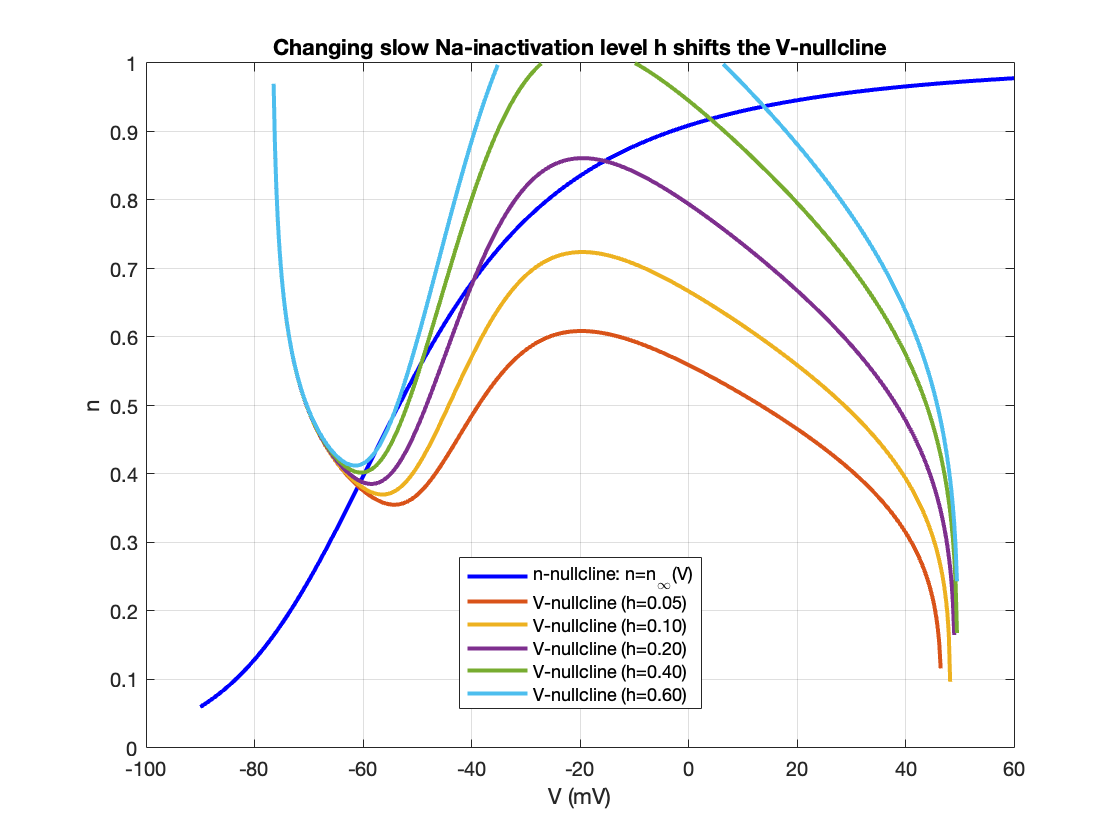


% [Insert slide image: reduced phase plane with nullclines and sample traj.]

%% ---------------- (c) HOW PHASE PORTRAIT SHIFTS WITH SLOW VARIABLE h ----
figure('Name','Effect of slow variable h on reduced V-nullcline');
plot(Vline, n_null, 'b', 'LineWidth', 2); hold on; grid on;
xlabel('V (mV)'); ylabel('n');
title('Changing slow Na-inactivation level h shifts the V-nullcline');
legendEntries = {'n-nullcline: n=n_\infty(V)'};

for hv = h_values_for_nullcline_scan
    nV = Vnullcline_n_of_V(Vline, HH, Iconst, hv);
    plot(Vline, nV, 'LineWidth', 2);
    legendEntries{end+1} = sprintf('V-nullcline (h=%.2f)', hv);
end
legend(legendEntries{:}, 'Location','best');

% Interpretation for class:
%   Higher h (less inactivation) => stronger Na current => V-nullcline shifts,
%   potentially changing the number/stability of fixed points (excitability).

% [Insert slide image: family of V-nullclines vs h]

%% ------------------ FITZHUGH--NAGUMO (2D CARICATURE) --------------------
% FitzHugh--Nagumo keeps the core geometric features:
%   - a cubic-like fast nullcline (v-nullcline)
%   - a slow recovery variable (w)
%   - relaxation oscillations when parameters yield a limit cycle

fprintf('Simulating FitzHugh--Nagumo (dimensionless) example...\n');

Simulating FitzHugh--Nagumo (dimensionless) example...


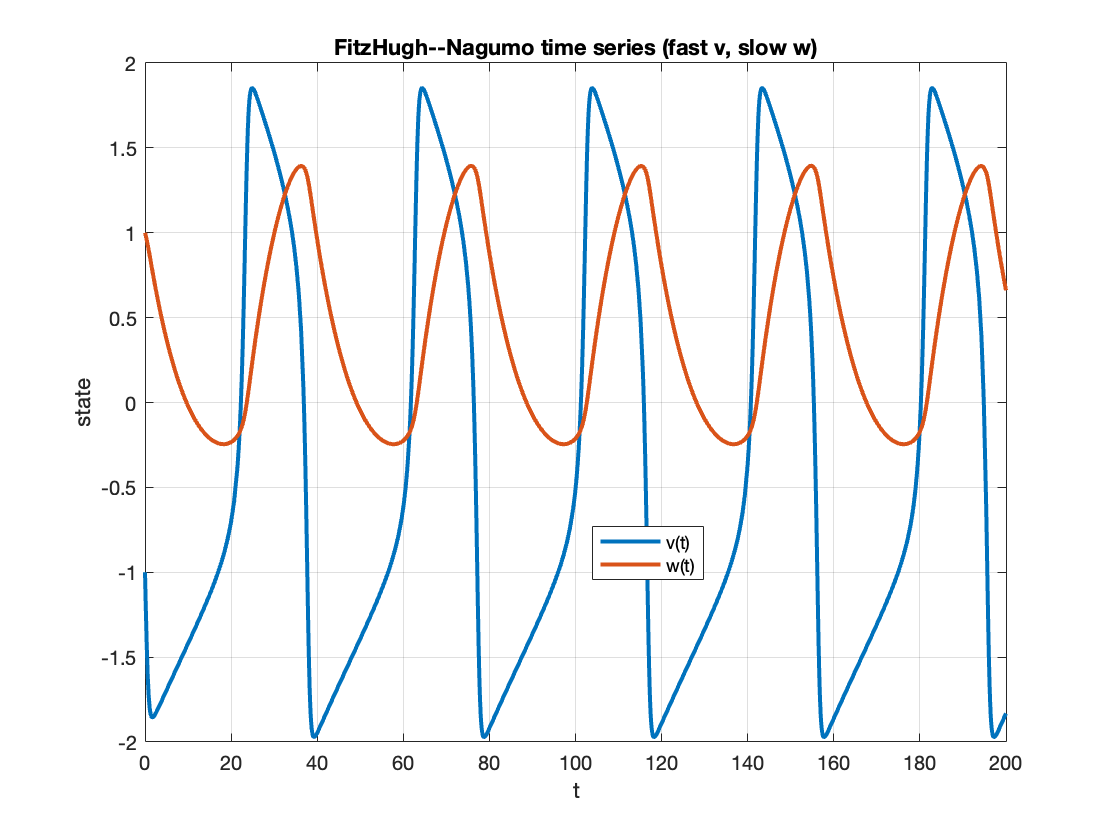

[tF, XF] = ode45(@(t,X) FHN_rhs(t,X,FHN), [0 FHN.Tend], [-1; 1]);  % initial condition

v = XF(:,1); w = XF(:,2);

figure('Name','FHN time series');
plot(tF, v, 'LineWidth', 2); hold on;
plot(tF, w, 'LineWidth', 2);
grid on; xlabel('t'); ylabel('state');
legend('v(t)','w(t)','Location','best');
title('FitzHugh--Nagumo time series (fast v, slow w)');

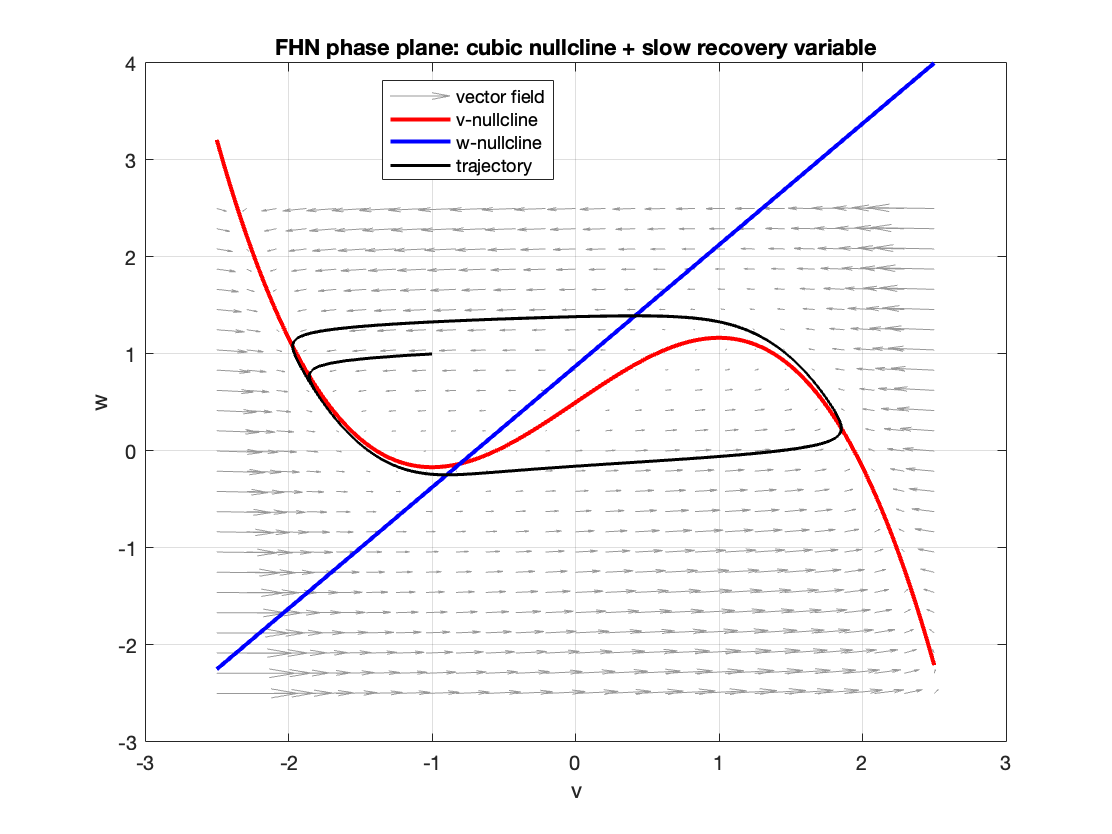


% Phase plane with nullclines
vline = linspace(-2.5, 2.5, 600);
w_vnull = vline - (vline.^3)/3 + FHN.I;      % \dot v=0
w_wnull = (vline + FHN.a)/FHN.b;             % \dot w=0

[Vf, Wf] = meshgrid(linspace(-2.5,2.5,25), linspace(-2.5,2.5,25));
[dvf, dwf] = FHN_field(Vf, Wf, FHN);

figure('Name','FHN phase plane');
quiver(Vf, Wf, dvf, dwf, 2, 'Color',[0.6 0.6 0.6]); hold on; grid on;
plot(vline, w_vnull, 'r', 'LineWidth', 2);
plot(vline, w_wnull, 'b', 'LineWidth', 2);
plot(v, w, 'k', 'LineWidth', 1.5);
xlabel('v'); ylabel('w');
legend('vector field','v-nullcline','w-nullcline','trajectory','Location','best');
title('FHN phase plane: cubic nullcline + slow recovery variable');

% [Insert slide image: FHN phase plane showing relaxation oscillation geometry]


%% ------------------- TEACHING CHECKLIST / DISCUSSION -------------------
% Suggested talking points as you run figures:
%
% (1) Biophysics: show V(t), then show INa vs IK to explain spike upstroke/repol.
% (2) Channel kinetics: show m,h,n time constants (tau_m << tau_h,tau_n).
% (3) Slow--fast: interpret m as quasi-steady, n as slow recovery variable.
% (4) Reduced portrait: show nullclines in (V,n); highlight how changing h moves V-nullcline.
% (5) Caricature: show FHN as "geometry-preserving" 2D model of excitability/spiking.
%
% Minimal slides to prepare:
%   [Slide A] m_inf/h_inf/n_inf and tau curves (1 slide)
%   [Slide B] HH spike + currents (1 slide)
%   [Slide C] Reduced phase plane (V,n) with nullclines (1 slide)
%   [Slide D] FHN phase plane with nullclines (1 slide)
%
% ------------------------------------------------------------------------
%% ----------------------------- FUNCTIONS -------------------------------

function I = I_step(t, I0, t_on, t_off)
    if t >= t_on && t <= t_off
        I = I0;
    else
        I = 0;
    end
end

function dX = HH_rhs(t, X, HH, Iapp)
    V = X(1); m = X(2); h = X(3); n = X(4);

    % Ionic currents
    INa = HH.gNa*(m^3)*h*(V - HH.ENa);
    IK  = HH.gK*(n^4)*(V - HH.EK);
    IL  = HH.gL*(V - HH.EL);

    % Membrane equation
    dV = (Iapp(t) - INa - IK - IL)/HH.Cm;

    % Gating kinetics
    am = alpha_m(V); bm = beta_m(V);
    ah = alpha_h(V); bh = beta_h(V);
    an = alpha_n(V); bn = beta_n(V);

    dm = am*(1-m) - bm*m;
    dh = ah*(1-h) - bh*h;
    dn = an*(1-n) - bn*n;

    dX = [dV; dm; dh; dn];
end

function [infv, tauv] = gate_inf_tau(V, alpha_fun, beta_fun)
    % If V is scalar: return scalar inf and tau
    a = alpha_fun(V); b = beta_fun(V);
    infv = a./(a+b);
    tauv = 1./(a+b);
    if isscalar(V)
        % Overload convenience: if scalar input, return just inf (as scalar)
        % when called with one output argument.
        % (MATLAB will ignore tauv if not requested.)
    end
end

function [dV, dn] = HH_reduced2D_field(V, n, HH, Iconst, h_fixed)
    % Vector field for reduced (V,n) system with m = m_inf(V) and fixed h.
    [m_inf, ~] = gate_inf_tau(V, @alpha_m, @beta_m);
    [n_inf, tau_n] = gate_inf_tau(V, @alpha_n, @beta_n);

    INa = HH.gNa .* (m_inf.^3) .* h_fixed .* (V - HH.ENa);
    IK  = HH.gK  .* (n.^4)              .* (V - HH.EK);
    IL  = HH.gL  .* (V - HH.EL);

    dV = (Iconst - INa - IK - IL)/HH.Cm;
    dn = (n_inf - n)./tau_n;
end

function dX = HH_reduced2D_rhs(~, X, HH, Iconst, h_fixed)
    V = X(1); n = X(2);
    [dV, dn] = HH_reduced2D_field(V, n, HH, Iconst, h_fixed);
    dX = [dV; dn];
end

function nV = Vnullcline_n_of_V(Vline, HH, Iconst, h_fixed)
    % Solve dV/dt = 0 for n(V), using m = m_inf(V), fixed h.
    % From:
    %   0 = I - gNa*m^3*h*(V-ENa) - gK*n^4*(V-EK) - gL*(V-EL)
    % => n^4 = [I - gNa*m^3*h*(V-ENa) - gL*(V-EL)] / [gK*(V-EK)]
    [m_inf, ~] = gate_inf_tau(Vline, @alpha_m, @beta_m);

    num = (Iconst - HH.gNa.*(m_inf.^3).*h_fixed.*(Vline - HH.ENa) - HH.gL.*(Vline - HH.EL));
    den = (HH.gK.*(Vline - HH.EK));

    rhs = num./den;

    nV = nan(size(Vline));
    mask = rhs > 0;                 % only real n when rhs>0
    nV(mask) = rhs(mask).^(1/4);

    % Clip to [0,1] for plotting (physical range); keep NaNs where invalid.
    nV(nV < 0 | nV > 1) = nan;
end

function dX = FHN_rhs(~, X, P)
    v = X(1); w = X(2);
    dv = v - v^3/3 - w + P.I;
    dw = P.eps*(v + P.a - P.b*w);
    dX = [dv; dw];
end

function [dv, dw] = FHN_field(v, w, P)
    dv = v - v.^3/3 - w + P.I;
    dw = P.eps*(v + P.a - P.b*w);
end

% -------------------- HH gating-rate functions (safe) -------------------
function a = alpha_n(V)
    a = 0.01 * vtrap(V + 55, 10);
end
function b = beta_n(V)
    b = 0.125 * exp(-(V + 65)/80);
end
function a = alpha_m(V)
    a = 0.1 * vtrap(V + 40, 10);
end
function b = beta_m(V)
    b = 4 * exp(-(V + 65)/18);
end
function a = alpha_h(V)
    a = 0.07 * exp(-(V + 65)/20);
end
function b = beta_h(V)
    b = 1 ./ (1 + exp(-(V + 35)/10));
end

function y = vtrap(x, yscale)
    % Numerically stable version of x/(1-exp(-x/yscale))
    % Here we implement: x/(1 - exp(-x/yscale)) = x / (1 - e^{-x/yscale})
    % For small x, use limit yscale.
    eps0 = 1e-6;
    y = zeros(size(x));
    small = abs(x) < eps0;
    y(small) = yscale;
    y(~small) = x(~small) ./ (1 - exp(-x(~small)/yscale));
end
